# Resample Data with Different Interpolation Methods 

This code loads and plots electrical conductivity data. 

concentration=[0 142 610 1170 2035 2297 2665 3264 3568 4349 5948]

concentration =            0         142         610        1170        2035        2297        2665        3264        3568        4349        5948


conductivity=[42 592 1040 1605 2170 2756 3137 4030 4341 4878 5115]

conductivity =           42         592        1040        1605        2170        2756        3137        4030        4341        4878        5115


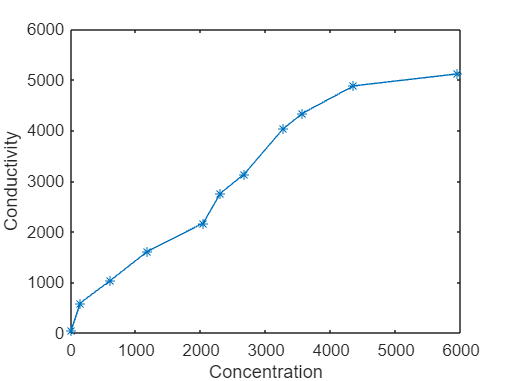

plot(concentration,conductivity,"*-");
xlabel("Concentration")
ylabel("Conductivity")

## Task 1

In this activity, you will continue working with the conductivity data.

You will find an even sampling of the data and use `interp1` with a different interpolation method.

Task

Use `linspace` to create a vector `xNew` of 100 equally spaced points in the interval 0 to 5000.

xNew=linspace(0,5000,100)

xNew = 1.0e+03 *

         0    0.0505    0.1010    0.1515    0.2020    0.2525    0.3030    0.3535    0.4040    0.4545    0.5051    0.5556    0.6061    0.6566    0.7071    0.7576    0.8081    0.8586    0.9091    0.9596    1.0101    1.0606    1.1111    1.1616    1.2121    1.2626    1.3131    1.3636    1.4141    1.4646    1.5152    1.5657    1.6162    1.6667    1.7172    1.7677    1.8182    1.8687    1.9192    1.9697    2.0202    2.0707    2.1212    2.1717    2.2222    2.2727    2.3232    2.3737    2.4242    2.4747


## Task 2

You can specify a fourth argument to `interp1` to choose an interpolation method. The default method is `"linear"`.

`yi` `=` `interp1``(``x``,``y``,``xi``,``method``)`

The output vector `yi` will be the interpolated values using the chosen interpolation method. 

Task

Find the interpolated value at each point in `xNew` using the `interp1` function with the `"spline"` interpolation method.

Assign the output to `yNew`.

yNew=interp1(concentration,conductivity,xNew,"spline")

yNew = 1.0e+03 *

    0.0420    0.2763    0.4665    0.6177    0.7348    0.8228    0.8865    0.9310    0.9612    0.9820    0.9984    1.0154    1.0379    1.0699    1.1112    1.1598    1.2140    1.2720    1.3319    1.3921    1.4507    1.5058    1.5557    1.5987    1.6331    1.6597    1.6800    1.6954    1.7075    1.7178    1.7278    1.7389    1.7527    1.7708    1.7945    1.8254    1.8650    1.9149    1.9765    2.0512    2.1408    2.2460    2.3628    2.4838    2.6019    2.7099    2.8007    2.8729    2.9307    2.9781


## Task 3

Use `hold` `on` to plot the interpolated conductivity values `yNew` as a function of concentration values `xNew` using circle markers `"o"` in the existing figure. 

Remember to use `hold` `off` when finished plotting.

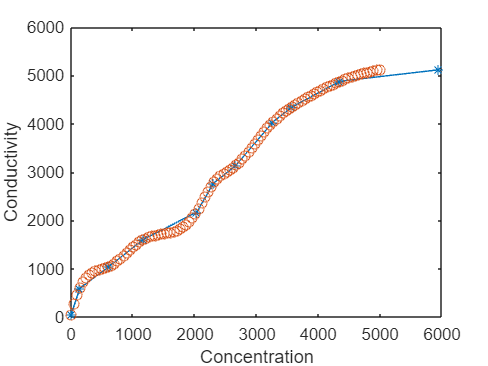

hold on
plot(xNew, yNew,"o")
hold off

## Further Practice

Spline interpolation finds a smooth interpolant by calculating the interpolated value using more than two neighboring points. 

Try using one of the other interpolation methods:

- `"nearest"`: The value of the nearest known data point

- `"next"`: The value of the next known data point

- `"pchip"`: Shape-preserving piecewise cubic interpolation

yNew2=interp1(concentration,conductivity,xNew,"nearest")

yNew2 =           42          42         592         592         592         592         592         592        1040        1040        1040        1040        1040        1040        1040        1040        1040        1040        1605        1605        1605        1605        1605        1605        1605        1605        1605        1605        1605        1605        1605        1605        2170        2170        2170        2170        2170        2170        2170        2170        2170        2170        2170        2756        2756        2756        2756        2756        2756        2756


yNew3=interp1(concentration,conductivity,xNew,"next")

yNew3 =           42         592         592        1040        1040        1040        1040        1040        1040        1040        1040        1040        1040        1605        1605        1605        1605        1605        1605        1605        1605        1605        1605        1605        2170        2170        2170        2170        2170        2170        2170        2170        2170        2170        2170        2170        2170        2170        2170        2170        2170        2756        2756        2756        2756        2756        3137        3137        3137        3137


yNew4=interp1(concentration,conductivity,xNew,"pchip")

yNew4 = 1.0e+03 *

    0.0420    0.2768    0.4836    0.6081    0.6841    0.7465    0.7981    0.8417    0.8800    0.9158    0.9519    0.9911    1.0362    1.0866    1.1390    1.1925    1.2468    1.3012    1.3551    1.4081    1.4594    1.5086    1.5550    1.5982    1.6374    1.6726    1.7044    1.7335    1.7605    1.7860    1.8107    1.8353    1.8603    1.8863    1.9142    1.9444    1.9777    2.0146    2.0558    2.1019    2.1537    2.2235    2.3346    2.4679    2.6019    2.7152    2.7921    2.8530    2.9052    2.9520


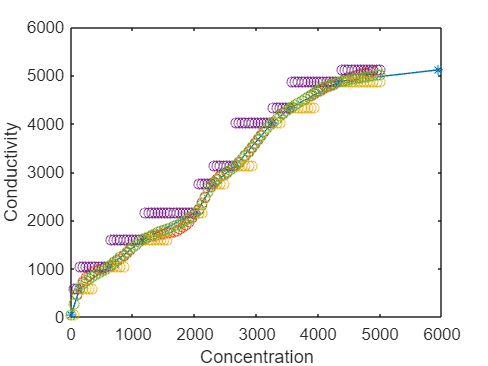

hold on
plot(xNew, yNew2,"o")
plot(xNew, yNew3,"o")
plot(xNew, yNew4,"o")
hold off